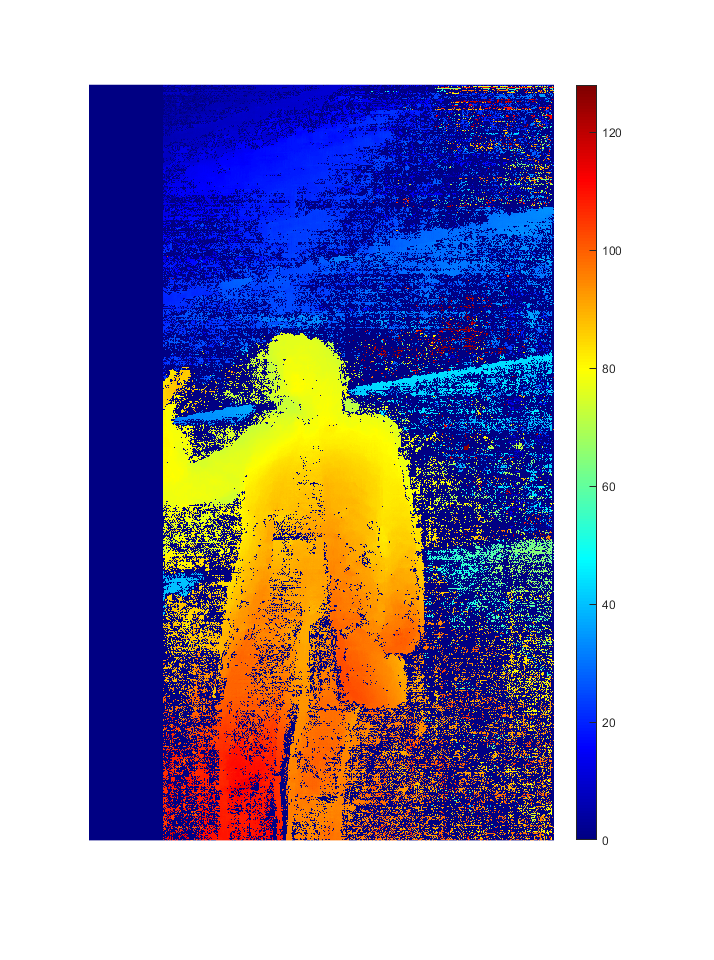

left = rgb2gray(imread("0002_L.png"));
right = rgb2gray(imread("0002_R.png"));
disparityRange = [0 128];
uniq = 10;
dispMap1 = disparitySGM(left,right, "DisparityRange", disparityRange, 'UniquenessThreshold',uniq);
%disparityRange = [-128 0];
dispMap2 = disparitySGM(flip(right,2),flip(left,2), "DisparityRange", disparityRange, 'UniquenessThreshold',uniq);



%imshow(dispMap1)
figure;
imshow(dispMap1, disparityRange)
colormap jet
colorbar

threshhold = 70;

%😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂
mask = dispMap1;

disp('Not a number removed')

Not a number removed


mask(mask ~= mask) = 0;
%imshow(mask)
disp('Medfilt')

Medfilt


mask = medfilt2(mask,[5 5]);
%imshow(mask)
disp('Gauss')

Gauss


mask = imgaussfilt(mask,5);
disp('Threshold applied')

Threshold applied


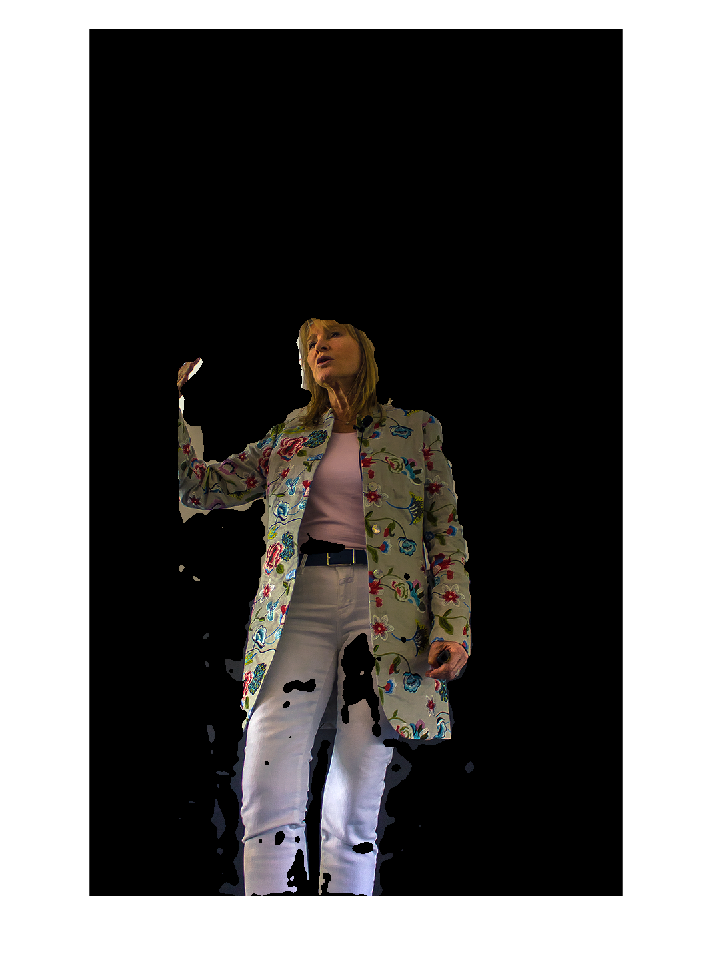

mask(mask < threshhold) = 0;
mask(mask >= threshhold) = 1;
%imshow(mask)


%imshow(mask)

%😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂

live = imread('0002_L.png');
for i = 1:3
    live(:,:,i) = immultiply(uint8(mask),live(:,:,i));
end

imshow(live)